# 创建深度学习网络架构

该脚本可创建具有以下属性的深度学习网络:

运行脚本以在工作区变量 `layers` 中创建层。

要了解详细信息，请参阅 [从 Deep Network Designer 生成 MATLAB 代码](matlab:helpview('deeplearning','generate_matlab_code'))。

由 MATLAB 于 2021-03-22 06:53:53 自动生成

## 创建层组

layers = [
    imageInputLayer([227 227 3],"Name","data")
    convolution2dLayer([11 11],96,"Name","conv1","BiasLearnRateFactor",2,"Stride",[4 4])
    reluLayer("Name","relu1")
    crossChannelNormalizationLayer(5,"Name","norm1","K",1)
    maxPooling2dLayer([3 3],"Name","pool1","Stride",[2 2])
    groupedConvolution2dLayer([5 5],128,2,"Name","conv2","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","relu2")
    crossChannelNormalizationLayer(5,"Name","norm2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2","Stride",[2 2])
    convolution2dLayer([3 3],384,"Name","conv3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu3")
    groupedConvolution2dLayer([3 3],192,2,"Name","conv4","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu4")
    groupedConvolution2dLayer([3 3],128,2,"Name","conv5","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu5")
    maxPooling2dLayer([3 3],"Name","pool5","Stride",[2 2])
    fullyConnectedLayer(4096,"Name","fc6","BiasLearnRateFactor",2)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop6")
    fullyConnectedLayer(4096,"Name","fc7","BiasLearnRateFactor",2)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop7")
    fullyConnectedLayer(1000,"Name","fc8","BiasLearnRateFactor",2)
    softmaxLayer("Name","prob")
    classificationLayer("Name","output")];

## 绘制层

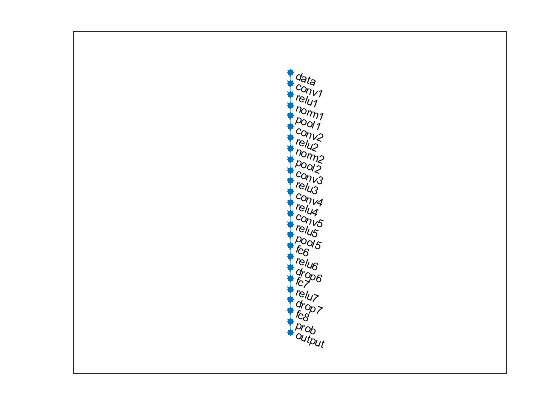

plot(layerGraph(layers));

# 使用预训练参数创建深度学习网络架构

该脚本可创建具有以下属性的深度学习网络:

运行脚本以在工作区变量 `layers` 中创建层。

要了解详细信息，请参阅 [从 Deep Network Designer 生成 MATLAB 代码](matlab:helpview('deeplearning','generate_matlab_code'))。

由 MATLAB 于 2021-03-22 06:54:31 自动生成

## 加载预训练参数

params = load("D:\R2020b\bin\win64\params_2021_03_22__06_54_26.mat");

## 创建层组

layers = [
    imageInputLayer([227 227 3],"Name","data","Mean",params.data.Mean)
    convolution2dLayer([11 11],96,"Name","conv1","BiasLearnRateFactor",2,"Stride",[4 4],"Bias",params.conv1.Bias,"Weights",params.conv1.Weights)
    reluLayer("Name","relu1")
    crossChannelNormalizationLayer(5,"Name","norm1","K",1)
    maxPooling2dLayer([3 3],"Name","pool1","Stride",[2 2])
    groupedConvolution2dLayer([5 5],128,2,"Name","conv2","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",params.conv2.Bias,"Weights",params.conv2.Weights)
    reluLayer("Name","relu2")
    crossChannelNormalizationLayer(5,"Name","norm2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2","Stride",[2 2])
    convolution2dLayer([3 3],384,"Name","conv3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",params.conv3.Bias,"Weights",params.conv3.Weights)
    reluLayer("Name","relu3")
    groupedConvolution2dLayer([3 3],192,2,"Name","conv4","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",params.conv4.Bias,"Weights",params.conv4.Weights)
    reluLayer("Name","relu4")
    groupedConvolution2dLayer([3 3],128,2,"Name","conv5","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",params.conv5.Bias,"Weights",params.conv5.Weights)
    reluLayer("Name","relu5")
    maxPooling2dLayer([3 3],"Name","pool5","Stride",[2 2])
    fullyConnectedLayer(4096,"Name","fc6","BiasLearnRateFactor",2,"Bias",params.fc6.Bias,"Weights",params.fc6.Weights)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop6")
    fullyConnectedLayer(4096,"Name","fc7","BiasLearnRateFactor",2,"Bias",params.fc7.Bias,"Weights",params.fc7.Weights)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop7")
    fullyConnectedLayer(1000,"Name","fc8","BiasLearnRateFactor",2,"Bias",params.fc8.Bias,"Weights",params.fc8.Weights)
    softmaxLayer("Name","prob")
    classificationLayer("Name","output","Classes",params.output.Classes)];

## 绘制层

plot(layerGraph(layers));